Function

f=@(x) (1 - x - 4.*x.^3 + 2.*x.^5)

f = function_handle with value:
    @(x)(1-x-4.*x.^3+2.*x.^5)


xx = linspace(-2,4)

xx =    -2.0000   -1.9394   -1.8788   -1.8182   -1.7576   -1.6970   -1.6364   -1.5758   -1.5152   -1.4545   -1.3939   -1.3333   -1.2727   -1.2121   -1.1515   -1.0909   -1.0303   -0.9697   -0.9091   -0.8485   -0.7879   -0.7273   -0.6667   -0.6061   -0.5455   -0.4848   -0.4242   -0.3636   -0.3030   -0.2424   -0.1818   -0.1212   -0.0606         0    0.0606    0.1212    0.1818    0.2424    0.3030    0.3636    0.4242    0.4848    0.5455    0.6061    0.6667    0.7273    0.7879    0.8485    0.9091    0.9697


yy = f(xx)

yy = 1.0e+03 *

   -0.0290   -0.0228   -0.0174   -0.0129   -0.0091   -0.0059   -0.0033   -0.0012    0.0005    0.0017    0.0027    0.0034    0.0038    0.0041    0.0042    0.0042    0.0041    0.0039    0.0037    0.0034    0.0031    0.0029    0.0026    0.0023    0.0021    0.0019    0.0017    0.0015    0.0014    0.0013    0.0012    0.0011    0.0011    0.0010    0.0009    0.0009    0.0008    0.0007    0.0006    0.0005    0.0003    0.0001   -0.0001   -0.0003   -0.0006   -0.0009   -0.0011   -0.0014   -0.0017   -0.0019


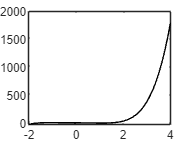

plot(xx,yy,'k-')

To integrate function from 0 to 0.8

a = -2

a = -2

b = 4

b = 4

p =[2 0 -4 0 -1 1]

p =      2     0    -4     0    -1     1


q = polyint(p)

q =     0.3333         0   -1.0000         0   -0.5000    1.0000         0


Itrue = diff(polyval(q,[a,b]))

Itrue = 1104

Plot original function along with trapezoidal rule ns = 1

ns = 1

ns = 1

x = linspace(a,b,ns+1)

x =     -2     4


y = f(x)

y =          -29        1789


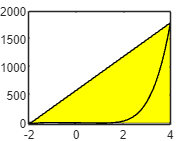


figure
area(x,y,'FaceColor','y','EdgeColor','black','LineStyle','-')
hold on
plot(xx,yy,'k-')

I_trap_1 = trap(f,a,b,1)

I_trap_1 = 5280


err = abs(Itrue - I_trap_1)/Itrue

err = 3.7826

err = err * 100

err = 378.2609

Plot original function along with trapezoidal rule ns = 2

ns = 2

ns = 2

x = linspace(a,b,ns+1)

x =     -2     1     4


y = f(x)

y =          -29          -2        1789



figure 
color=['g','y']

color = 'gy'

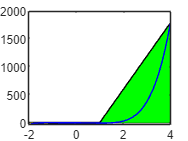

for i = 1:ns
    area(x(i:i+1),y(i:i+1),'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')    
    hold on
end
plot(xx,yy,'b-')

I_trap_2 = trap(f,a,b,2)

I_trap_2 = 2634

err = abs(Itrue - I_trap_2)/Itrue

err = 1.3859

err = err * 100

err = 138.5870

Plot original function along with trapezoidal rule ns = 3

ns = 3

ns = 3

x = linspace(a,b,ns+1)

x =     -2     0     2     4


y = f(x)

y =          -29           1          31        1789



figure 
color=['g','y']

color = 'gy'

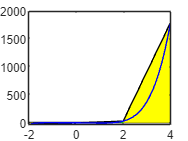

for i = 1:ns
    area(x(i:i+1),y(i:i+1),'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')    
    hold on
end
plot(xx,yy,'b-')

ns = 4

ns = 4

x = linspace(a,b,ns+1)

x =    -2.0000   -0.5000    1.0000    2.5000    4.0000


y = f(x)

y = 1.0e+03 *

   -0.0290    0.0019   -0.0020    0.1313    1.7890



figure 
color=['g','y']

color = 'gy'

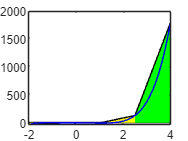

for i = 1:ns
    area(x(i:i+1),y(i:i+1),'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')    
    hold on
end
plot(xx,yy,'b-')

I_trap_4 = trap(f,a,b,4)

I_trap_4 = 1.5169e+03

err = abs(Itrue - I_trap_4)/Itrue

err = 0.3740

err = err * 100

err = 37.3981

Plot original function along with trapezoidal rule ns from 1 until 10

Plot original function along with trapezoidal rule ns = 3

ns = 5

x =    -2.0000   -0.8000    0.4000    1.6000    2.8000    4.0000


y = 1.0e+03 *

   -0.0290    0.0032    0.0004    0.0040    0.2546    1.7890


color = 'gy'

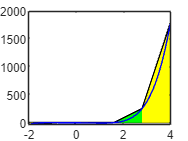

ns = 6

x =     -2    -1     0     1     2     3     4


y =          -29           4           1          -2          31         376        1789


color = 'gy'

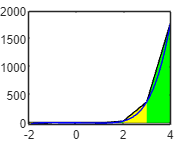

ns = 7

x =    -2.0000   -1.1429   -0.2857    0.5714    1.4286    2.2857    3.1429    4.0000


y = 1.0e+03 *

   -0.0290    0.0042    0.0014   -0.0002   -0.0002    0.0757    0.4870    1.7890


color = 'gy'

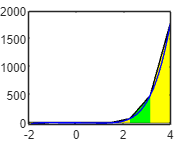

ns = 8

x =    -2.0000   -1.2500   -0.5000    0.2500    1.0000    1.7500    2.5000    3.2500    4.0000


y = 1.0e+03 *

   -0.0290    0.0040    0.0019    0.0007   -0.0020    0.0106    0.1313    0.5856    1.7890


color = 'gy'

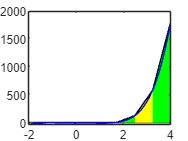

ns = 9

x =    -2.0000   -1.3333   -0.6667         0    0.6667    1.3333    2.0000    2.6667    3.3333    4.0000


y = 1.0e+03 *

   -0.0290    0.0034    0.0026    0.0010   -0.0006   -0.0014    0.0310    0.1922    0.6726    1.7890


color = 'gy'

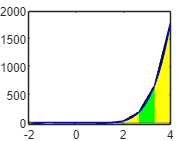

ns = 10

x =    -2.0000   -1.4000   -0.8000   -0.2000    0.4000    1.0000    1.6000    2.2000    2.8000    3.4000    4.0000


y = 1.0e+03 *

   -0.0290    0.0026    0.0032    0.0012    0.0004   -0.0020    0.0040    0.0593    0.2546    0.7491    1.7890


color = 'gy'

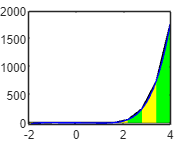

ns = 11

x =    -2.0000   -1.4545   -0.9091   -0.3636    0.1818    0.7273    1.2727    1.8182    2.3636    2.9091    3.4545    4.0000


y = 1.0e+03 *

   -0.0290    0.0017    0.0037    0.0015    0.0008   -0.0009   -0.0018    0.0149    0.0934    0.3163    0.8166    1.7890


color = 'gy'

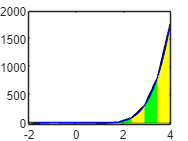

ns = 12

x =    -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000


y = 1.0e+03 *

   -0.0290    0.0008    0.0040    0.0019    0.0010    0.0001   -0.0020    0.0012    0.0310    0.1313    0.3760    0.8764    1.7890


color = 'gy'

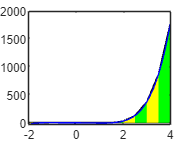

ns = 13

x =    -2.0000   -1.5385   -1.0769   -0.6154   -0.1538    0.3077    0.7692    1.2308    1.6923    2.1538    2.6154    3.0769    3.5385    4.0000


y = 1.0e+03 *

   -0.0290   -0.0001    0.0042    0.0024    0.0012    0.0006   -0.0011   -0.0020    0.0077    0.0516    0.1716    0.4330    0.9297    1.7890


color = 'gy'

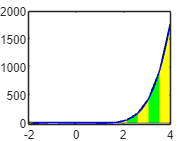

ns = 14

x =    -2.0000   -1.5714   -1.1429   -0.7143   -0.2857    0.1429    0.5714    1.0000    1.4286    1.8571    2.2857    2.7143    3.1429    3.5714    4.0000


y = 1.0e+03 *

   -0.0290   -0.0011    0.0042    0.0028    0.0014    0.0008   -0.0002   -0.0020   -0.0002    0.0177    0.0757    0.2129    0.4870    0.9773    1.7890


color = 'gy'

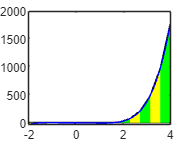

for i = 1:10
    ns = ns+1
    x = linspace(a,b,ns+1)
    y = f(x)

    figure 
    color=['g','y']
    for i = 1:ns
        area(x(i:i+1),y(i:i+1),'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')
        hold on
    end
    plot(xx,yy,'b-')
end